# 02E. Bifurcation

## Mingyang Lu

## 01/07/2024

Consider one self-activating gene, 

$\frac{dX}{dt}=f(X,k)=10+45\frac{X^4 }{X^4 +200^4 }-kX$.

### Method 1: (direct method) find all roots[¶](http://localhost:8888/notebooks/02E.ipynb#Method-1:-(direct-method)-find-all-roots)

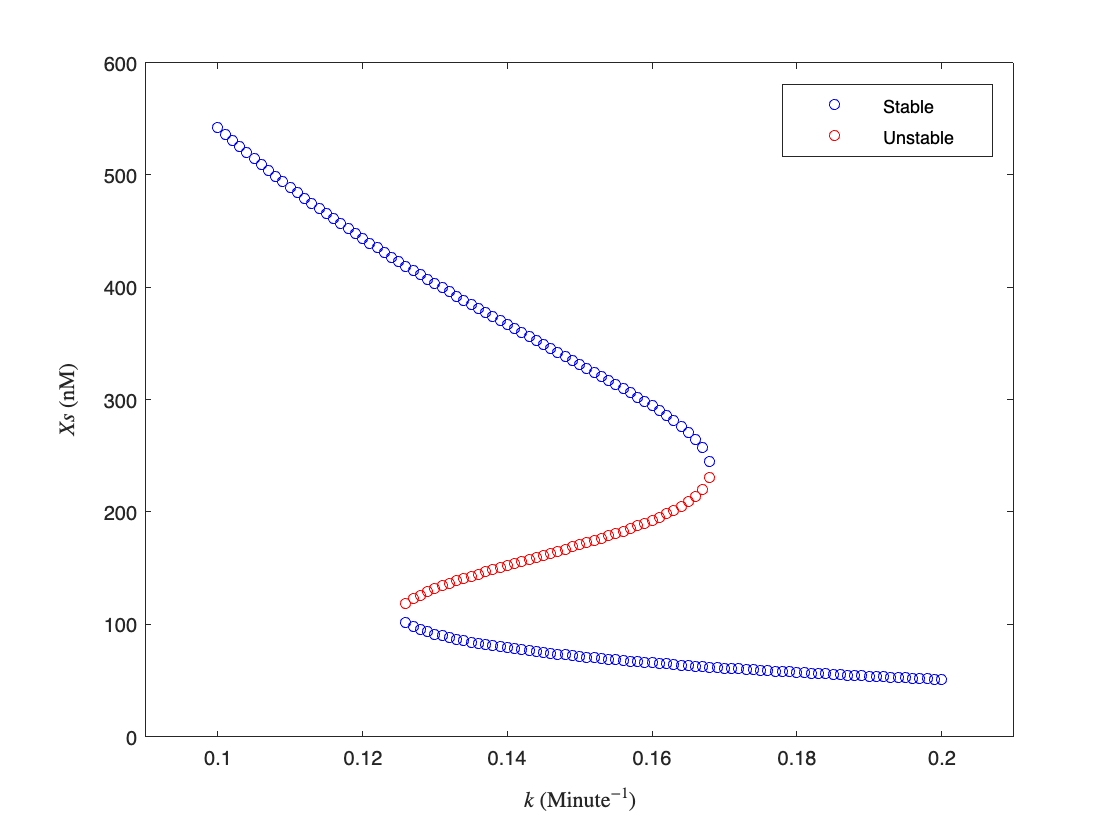

% dX is used to estimate the derivatives of f(X) near the steady states
dX = 0.1;

% All k values to be sampled (control parameter)
k_all = 0.1:0.001:0.2;

% bifurcation
results = zeros(301,3);
n_points = 0;

for i = 1:101
    k = k_all(i);
    fun = @(X) derivs_k(X,k);
    X0_all = 0:50:1000;
    x1 = zeros(1,21);
    for j = 1:length(X0_all)
       X1(j) = fzero(fun,X0_all(j));
    end
    X_new = unique(X1);
    for j = 1:length(X_new)
        X = X_new(j);
        if X >= 0 && X <= 800
        % df/dX < 0, stable
            if sign(derivs_k(X + dX, k)) < 0
                stability = 1;
            else
                stability = 2;
            end
            n_points = n_points + 1;
            results(n_points,:) = [k, X, stability];
        end
    end
end

% Plot the results
gscatter(results(:, 1), results(:, 2), results(:,3), 'br', 'o', 5);
xlabel('$k$ (Minute$^{-1}$)', 'Interpreter', 'latex');
ylabel('$Xs$ (nM)', 'Interpreter', 'latex');
xlim([0.09, 0.21]);
ylim([0, 600]);

% Create legend
legend('Stable', 'Unstable', 'Location', 'northeast');

### Method 2: Get bifurcation curve by simulations

See NumericalR for details of the algorithm.

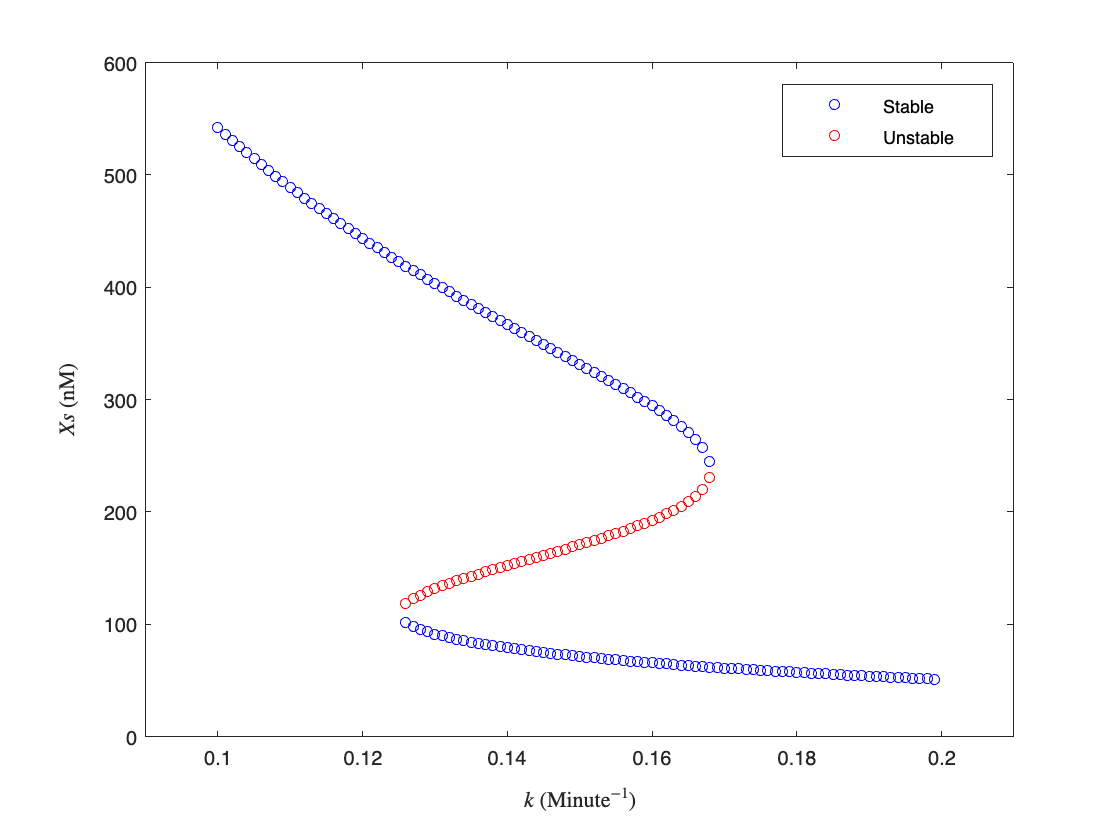

% Algorithm parameters
gap = 100.0;    % the stop criterion for a bifurcation point
t_max = 1000.0;  % Maximum ODE simulation time
dk = 0.001;      % k step size
dX = 1;          % small step in X to estimate df/dX

% Initialize parameters
k = 0.1;
X0 = randi([100, 600]);  % Random initial condition of X
d = 1;
ind = 0; % Record the index of steady states

% Initialize results storage
results = NaN(1000, 3);

while k < 0.2
    % Simulate until a stable steady state is reached
    options = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);
    [~, X] = ode45(@(t, X) derivs_k_adj(t, X, k, d), [0, t_max], X0, options);
    Xi = X(end);

    % Check for bifurcation point, switch the sampling direction of k.
    if ind > 0 && abs(Xi - X0) > gap
        d = -d;
        % Update k
        k = k + d * dk;
        % Update X0, with slight perturbation along the same direction from X0 to Xi in the current step
        X0 = X0 + dX * sign(Xi - X0);
    else
        % Determine stability of the steady state
        f_x_plus_dx = derivs_k_adj(0, Xi + dX, k, 1);
        if sign(f_x_plus_dx) < 0  % df/dX < 0, stable
            stability = 1;
        else
            stability = 2;
        end
        
        % Record the steady state
        ind = ind + 1;
        results(ind, :) = [k, Xi, stability];
        
        % Update k and the initial X for the next iteration
        k = k + d * dk;
        X0 = Xi;
    end
end

% Trim excess NaNs from results matrix
results = results(1:ind, :);

% Plot the bifurcation diagram
gscatter(results(:, 1), results(:, 2), results(:,3), 'br', 'o', 5);

xlabel('$k$ (Minute$^{-1}$)', 'Interpreter', 'latex');
ylabel('$Xs$ (nM)', 'Interpreter', 'latex');
xlim([0.09, 0.21]);
ylim([0, 600]);

% Create legend
legend('Stable', 'Unstable', 'Location', 'northeast');

### Method 3: numerical continuation

Starting from a steady state $X$ for a specific $k$, we can obtain the slope of the bifurcation curve $\frac{dX}{dk}$ from

$\frac{dX}{dk}\equiv h(X,k)=-\frac{\frac{\partial f}{\partial k}}{\frac{\partial f}{\partial X}}$.

This allows us to find the initial guess of the next ($k$, $X$) point. 


$$\begin{cases} k_{new} = k + \Delta k \\
              X_{new} = X +  \frac{dX}{dk}\Delta k  \end{cases}$$


We can then use a correction method, such as Newton's method, to find the nearby solution.

#### Newton's method

We solve $f(X)=0$ starting from an initial guess at $X_0$. 

$f(X_0 +\Delta X)=f(X_0 )+f^{\prime } (X_0 )\Delta X=0$.

Thus,

$\Delta X=-\frac{f(X_0 )}{f^{\prime } (X_0 )}$.

Numerically, we perform the following calculation iteratively:

$X_{n+1} =X_n -\frac{f(X_n )}{f^{\prime } (X_n )}$, until $|f(X_{n+1} )|<\epsilon$, where $\epsilon$ is a small constant. Below shows the implementation of Newton's method for the current system.

% Example usage of find_root_Newton
% Monostable, one root
X_root1 = find_root_Newton(500, @derivs_k, @dfdX, [0, 800], 1e-3, 0.1);
% Bistable, first root near 500
X_root2 = find_root_Newton(500, @derivs_k, @dfdX, [0, 800], 1e-3, 0.15);
% Another root near 100
X_root3 = find_root_Newton(100, @derivs_k, @dfdX, [0, 800], 1e-3, 0.15);
% The last root (unstable) near 150
X_root4 = find_root_Newton(150, @derivs_k, @dfdX, [0, 800], 1e-3, 0.15);

% Display the roots
disp(['Root 1: ', num2str(X_root1)]);

Root 1: 541.7967


disp(['Root 2: ', num2str(X_root2)]);

Root 2: 331.6144


disp(['Root 3: ', num2str(X_root3)]);

Root 3: 71.484


disp(['Root 4: ', num2str(X_root4)]);

Root 4: 170.7466


### An implementation of the continuation method

Now, we implement the numerical continuation method by uniformly varying $k$.

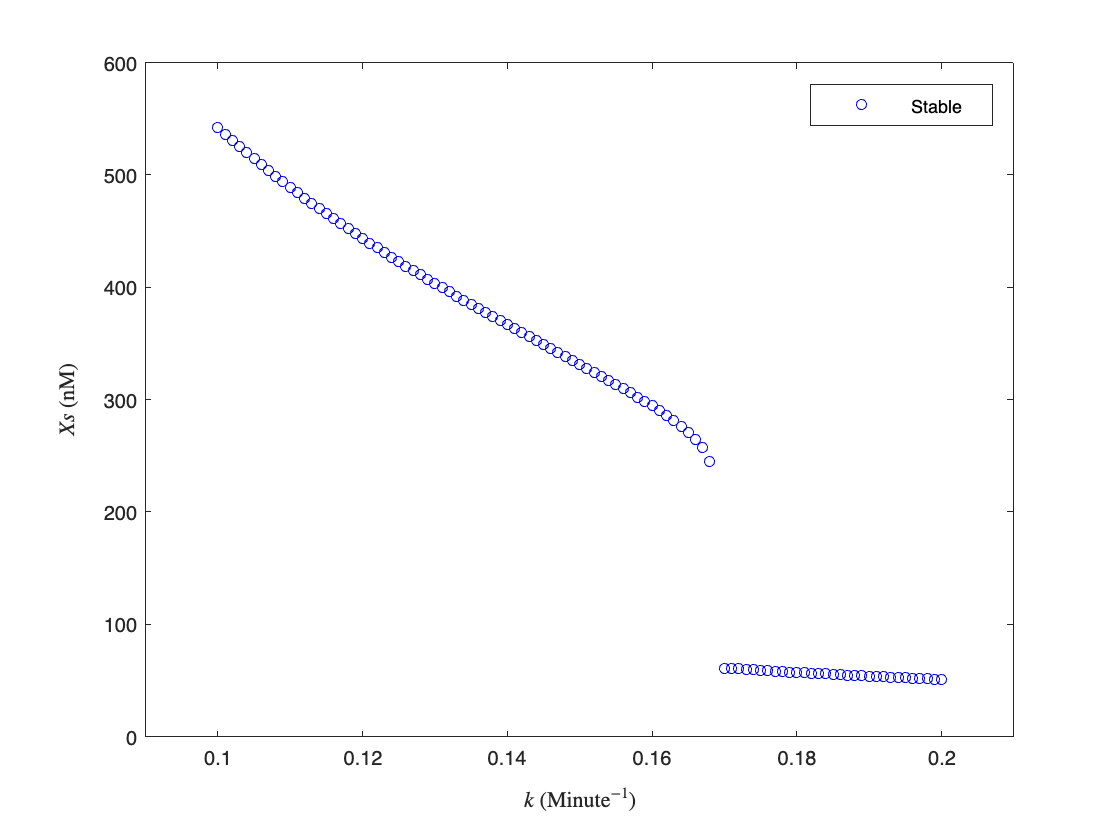

% Define the partial derivative df/dk
dfdk = @(X, k) -X;

% Algorithm parameters
X_init = 0;           % Initial condition of X
k_range = [0.1, 0.2]; % Range of parameter k
dk = 0.001;           % Step size for parameter k
nmax_cycle = (k_range(2) - k_range(1))/dk + 1; % Maximum number of cycles

% Create a matrix to store results
results_1 = NaN(nmax_cycle, 3);

cycle = 1;
k = 0.1;

% Obtain initial steady-state X
X_new = fzero(@(X) derivs_k(X,k),X_init);
results_1(cycle, :) = [k, X_new, -sign(dfdX(X_new, k))];

while ( (k - k_range(1)) * (k - k_range(2)) <= 0 ) % Check if k is in the range of [k_min, k_max]
    % Compute the slope of the bifurcation curve
    slope = -dfdk(X_new, k) / dfdX(X_new, k);
    
    k = k + dk;
    X_init = X_new + dk * slope;

    % Correction using Newton's method
    X_new = find_root_Newton(X_init, @derivs_k, @dfdX, [0, 800], 1e-3, k);

    cycle = cycle + 1;
    % Store results
    results_1(cycle, :) = [k, X_new, -sign(dfdX(X_new, k))];
end

% Trim results matrix
results_1 = results_1(1:cycle, :);

% Plot the bifurcation diagram
gscatter(results_1(:, 1), results_1(:, 2), (3-results_1(:,3)/2), 'br', 'o', 5);

xlabel('$k$ (Minute$^{-1}$)', 'Interpreter', 'latex');
ylabel('$Xs$ (nM)', 'Interpreter', 'latex');
xlim([0.09, 0.21]);
ylim([0, 600]);
% Create legend
legend('Stable', 'Unstable', 'Location', 'northeast');

This algorithm doesn't work at the bifurcation point, where the the slope of the curve becomes infinity.

### Improved continuaton method using arc length

We describe the bifurcation curve as the function of arc length $s$, instead of the control parameter $k$. Previously we aim to find $X(k)$, but here we will find $X(s)$ and $k(s)$.


$$\begin{cases} 
  \Delta s^2 = \Delta k^2 + \Delta X^2 \\
  \Delta X = h \Delta k  \end{cases}$$


Therefore, we get


$$\begin{cases} \Delta k = \pm \frac{1}{\sqrt{1 + h^2}} \Delta s \\
              \Delta X = h \Delta k \end{cases}$$


,where $h(X,k)=\frac{dX}{dk}$. In this case, even when $h$ is infinity, $\Delta k$ and $\Delta X\;$are small enough. The choice of $\pm \;$would depend on which direction we want to go. Here, we set $(\Delta k,\Delta X)$ to be in the same direction as that in the previous step.

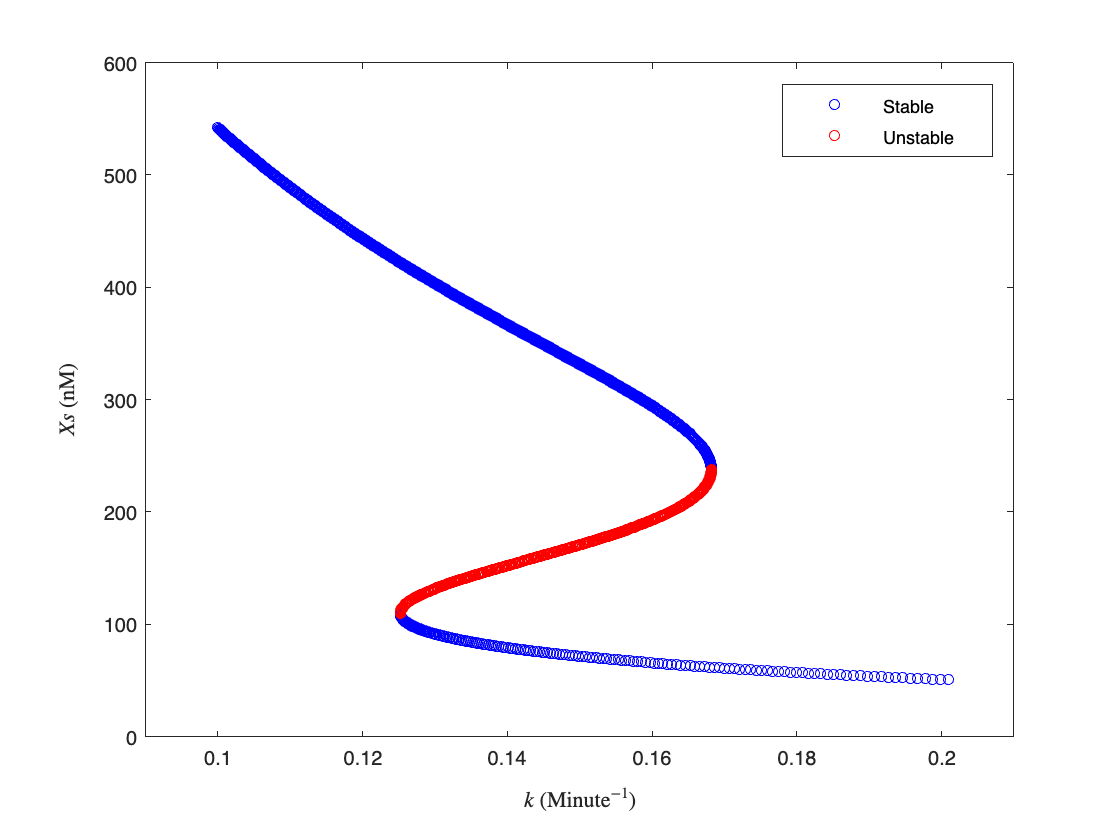

% Algorithm parameters
X_init = 0;         % Initial condition of X
k_range = [0.1, 0.2]; % Range of parameter k
ds = 0.3;           % Step size for the arc length
nmax_cycle = 10000; % Maximum number of cycles

% Create a matrix to store results
results_2 = NaN(nmax_cycle, 3);

cycle = 1;
k = 0.1;
step_k_previous = 1; % Initial step_k is positive
step_X_previous = 0;

% Obtain initial steady-state X
X_new = fzero(@(X) derivs_k(X,k),X_init);
results_2(cycle, :) = [k, X_new, -sign(dfdX(X_new, k))];

while (k_range(1) <= k && k <= k_range(2) && cycle < nmax_cycle)
    h = -dfdk(X_new, k) / dfdX(X_new, k);

    step_k = ds / sqrt(1 + h^2);
    step_X = step_k * h;

    % The direction of change should be the same along the search
    if (step_k_previous * step_k + step_X_previous * step_X < 0)
        step_k = -step_k;
        step_X = -step_X;
    end

    step_k_previous = step_k;
    step_X_previous = step_X;

    k = k + step_k;
    X_init = X_new + step_X;

    % Correction using Newton's method
    X_new = find_root_Newton(X_init, @derivs_k, @dfdX, [0, 800], 1e-3, k);

    cycle = cycle + 1;
    results_2(cycle, :) = [k, X_new, -sign(dfdX(X_new, k))];
end

% Trim results matrix
results_2 = results_2(1:cycle, :);

% Plot the bifurcation diagram
gscatter(results_2(:, 1), results_2(:, 2), (3-results_2(:,3)/2), 'br', 'o', 5);

xlabel('$k$ (Minute$^{-1}$)', 'Interpreter', 'latex');
ylabel('$Xs$ (nM)', 'Interpreter', 'latex');
xlim([0.09, 0.21]);
ylim([0, 600]);
% Create legend
legend('Stable', 'Unstable', 'Location', 'northeast');

### Define MATLAB functions

1. Define the derivative function 

function dXdt = derivs_k(X, k)
    dXdt = 10 + 45 * (1 - 1 / (1 + (X / 200)^4)) - k * X;
end

2. Define the derivative function (ajusted to allow searching for stable/unstable steady states from ODE simulations)

% k: control parameter; d: 1 - stable steady state; 2 - unstable steady state
function dXdt = derivs_k_adj(t, X, k, d)
    dXdt = d * (10 + 45 * (1 - 1 / (1 + (X / 200)^4)) - k * X);
end

3. Implementation of Newton's method to find a root of the function "func"

function X_root = find_root_Newton(X, func, dfunc, X_range, error, varargin)
    f = func(X, varargin{:});
    
    while abs(f) > error
        X = X - f/dfunc(X, varargin{:});
        
        % Check if X is within X_range
        if (X - X_range(1)) * (X - X_range(2)) > 0
            break;  % Avoid potential infinite loop
        end
        
        f = func(X, varargin{:});
    end
    
    X_root = X;
end

4.Define dfdX function

function result = dfdX(X, k)
    x_frac = (X/200)^4;
    result = 180 /X * x_frac / (1 + x_frac)^2 - k;
end